unreacheable


k = 80

APF global
find Goal!
unreacheable
APF global
find Goal!
APF global
unreacheable
find Goal!
unreacheable
APF global
find Goal!
unreacheable
APF global
find Goal!
APF global
find Goal!
unreacheable
APF global
find Goal!
unreacheable
APF global
find Goal!
APF global
find Goal!


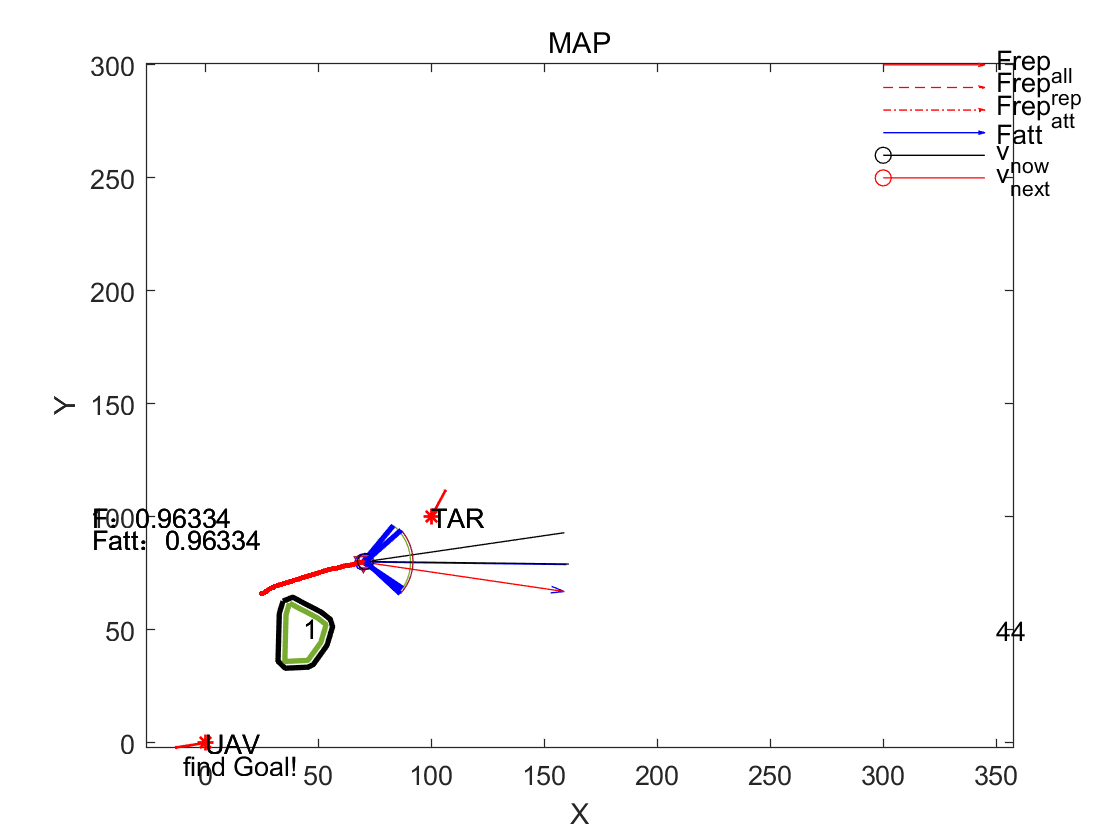


angle_CCW_CW=[];



obs_all=obs_param{1};
obs_unknow=obs_param{2};
obs_no_circle=obs_param{3};
obs_no_circle_in=obs_param{4};
num_obs=obs_param{5};
obs=obs_param{6};
obs_no_circle_unknow=obs_param{7};
obs_no_circle_in_unknow=obs_param{8};

obs_finall=[];

Stepsize=step_param(2);
step=step_param(3);

Start_Point=A_dubins_param{1};
End_Point=A_dubins_param{2};
sure=A_dubins_param{3};
r=A_dubins_param{4};
draw_path=A_dubins_param{5};

flag_realdager=0;
flag_new=0;
 min_obs=[0,0,inf];
flag_danger=0;
unreacheable=0;
flag_danger_fuck=0;
empty_flag=0;
dis_to_end=[];

fov=84;
k_att=1.5;
k_rep=30;
K=1000;
r_search=3*r;

% path_apf_all=[];
path_apf_all={};
path_apf=[];
% X_now_APF=[35,30];

% X_APF_final=[70,80];
End_point_apf=[70,80];
ll=10;
Stepsize_apf=1/ll*pi/2*r;
k=1;
for i=1:5:45
X_now_APF=[25,25+i];
angle=atan2(End_point_apf(2)-X_now_APF(2),End_point_apf(1)-X_now_APF(1));
% angle=-pi+rand(1)*2*pi;
[path_apf_all{k},X_APF_final_id]=APFtest(fov,k_att,k_rep,K,r_search,Stepsize_apf,X_now_APF,End_point_apf,angle,step_param,obs_param,A_dubins_param,X_APF_final_id);
k=k+1;
end

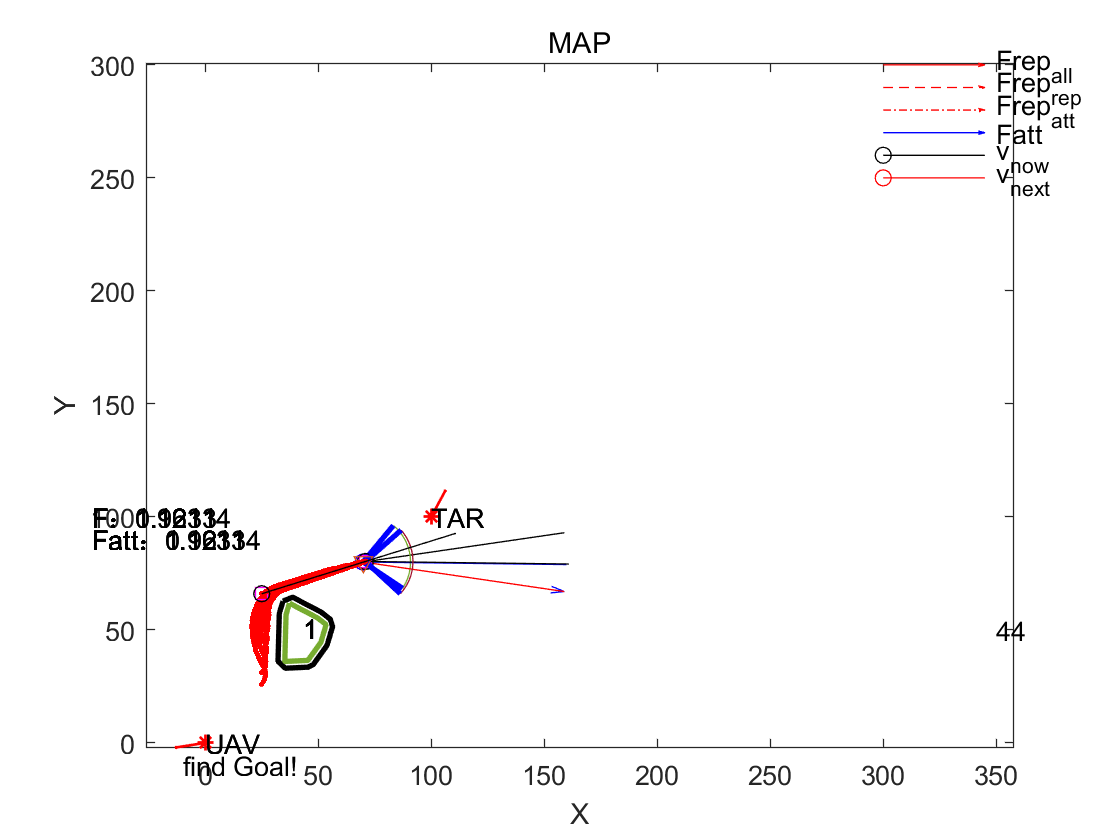

for i=1:length(path_apf_all)
draw_all(X_now_APF,X_APF_final,X_now_APF,path_apf_all{i},angle,obs_no_circle_unknow,obs_no_circle_in_unknow,F,Fatt)
end